# Minimum Variance Distortionless Response (MVDR) Lab

In this lab, we demonstrate MVDR, which is a classical adaptive beamforming technique. This technique allows us to filter out the presence of unwanted signals such as noise sources or jammers that are present in the environment.

In this lab, due to limitations of the Phaser board, we use data that was pre-collected on a board with 16 receive channels. To demonstrate the usefulness of adaptive filtering techniques, data was collected with 3 signal sources in the environment. Source C is considered to transmit the signal of interest, and source A and B are transmitting unwanted jamming signals.

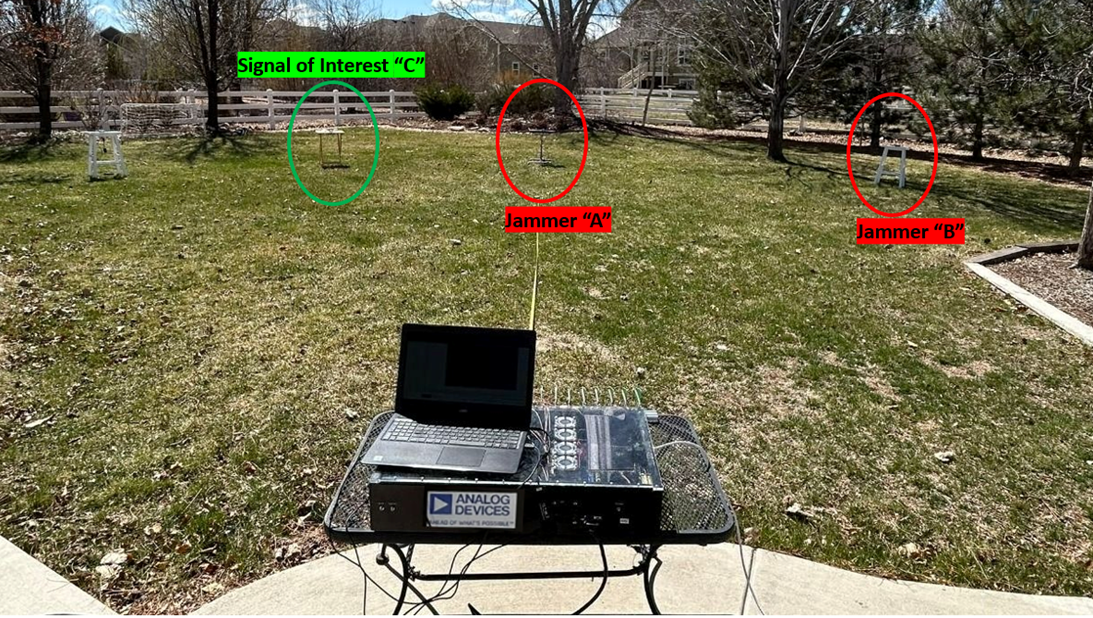 

The antenna array being used to collect signals is a uniform linear array that contains 16 elements and is operating at 3.3 GHz.

nElements = 16;
fc = 3.3e9;
lambda = freq2wavelen(fc);
array = phased.ULA(nElements,lambda/2);

Two sets of data are collected:

- A set containing transmissions from the environment when the signal of interest is not present - i.e. only the jammers A and B are transmitting. This is called the training data set.

- A set containing transmissions from all three sources simulatanously including the signal of interest C as well as the jammers A and B.

The purpose of this demonstration is to show that by using the data that is captured from the environment without our signal of interest, we can reduce the effects of the jammers on our collected signal.

These two sets of data are loaded below.

load('mvdrData.mat');

## MVDR Response

We can use the MVDR Estimator to apply the beamforming weights generated using the MVDR algorithm to the signal accross a range of angles. This gives us a response that indicates the direction of arrival (DOA) of the signals.

We compare the response of the data set containing only the jammers to the deta set containing the jammers as well as the signal of interest.

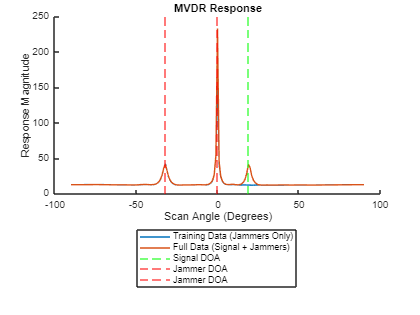

% Create estimator that scans from -90 to 90
angles = -90:90;
trainMvdrEstimator = phased.MVDREstimator(SensorArray=array,OperatingFrequency=fc,ScanAngles=angles,DOAOutputPort=true,NumSignals=2);
fullMvdrEstimator = phased.MVDREstimator(SensorArray=array,OperatingFrequency=fc,ScanAngles=angles,DOAOutputPort=true,NumSignals=3);

% Generate responses and get DOAs
[trainResponse,jamDoas] = trainMvdrEstimator(sigTrain);
[fullResponse,allDoas] = fullMvdrEstimator(sig);

% Signal DOA found by removing the jamming DOAs found in the training data
signalDoa = setdiff(allDoas,jamDoas);

% Plot response
ax = axes(figure);
hold(ax,"on");
plot(ax,angles,trainResponse,DisplayName="Training Data (Jammers Only)");
plot(ax,angles,fullResponse,DisplayName="Full Data (Signal + Jammers)");
xline(ax,signalDoa,DisplayName='Signal DOA',LineStyle='--',Color='g');
xline(ax,jamDoas,DisplayName='Jammer DOA',LineStyle='--',Color='r');
title(ax,"MVDR Response");
ylabel(ax,"Response Magnitude");
xlabel(ax,"Scan Angle (Degrees)")
legend(ax,Location="southoutside");

We can see that the responses are very similar, with the exception of the missing peak in the training data. This missing peak is our signal of interest. We use the missing peak location to get the angle of our signal of interest.

## MVDR Beamforming 

When we using the MVDR algorithm to amplify desired signals while suppressing undesired signals, it is important to have a training dataset. If we use MVDR to generate weights using data that contains the desired signal, then the algorithm will attempt to cancel this signal. This issue is mitigated by using training data that does not contain the desired signal.

We demonstrate this concept in this section by looking at the antenna pattern generated when using the weights output from the MVDR algorithm with the training dataset and the full dataset.

To do so we can use the mvdrweights function. This function is used internally by the MVDR estimator when we steer to each of the specified scan angles.

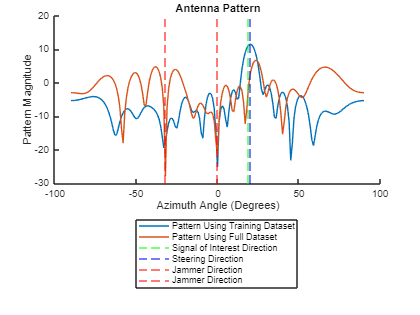

% Initially set the steering angle to our target of interest
steerAngle = 20;

% Steer towards the signal of interest with full data and training data
elPos = array.getElementPosition()/lambda;
trainWeights = mvdrweights(elPos,steerAngle,cov(conj(sigTrain)));
fullWeights = mvdrweights(elPos,steerAngle,cov(conj(sig)));

% Get the antenna pattern using the training weights and the full weights
trainPat = pattern(array,fc,angles,0,Weights=trainWeights);
fullPat = pattern(array,fc,angles,0,Weights=fullWeights);

% Plot the antenna patterns generated when using the weights from training
% data vs. full data
ax = axes(figure);
hold(ax,"on");
plot(ax,angles,trainPat,DisplayName="Pattern Using Training Dataset");
plot(ax,angles,fullPat,DisplayName="Pattern Using Full Dataset");
xline(ax,signalDoa,DisplayName='Signal of Interest Direction',LineStyle='--',Color='g');
xline(ax,steerAngle,DisplayName='Steering Direction',LineStyle='--',Color='b');
xline(ax,jamDoas,DisplayName='Jammer Direction',LineStyle='--',Color='r');
title(ax,"Antenna Pattern");
ylabel(ax,"Pattern Magnitude");
xlabel(ax,"Azimuth Angle (Degrees)")
legend(ax,Location="southoutside");